# **W4 Artificial Potential Fields**

#### **Robotics: Computational Motion Planning**

**University of Pennsylvania  |  Coursera**

clear;
close all;
clc;

## Generate Several Points

nrows = 400;
ncols = 600;

obstacle = false(nrows, ncols);

[x, y] = meshgrid (1:ncols, 1:nrows);

## Generate Several Obstacle

obstacle (300:end, 100:250) = true;
obstacle (150:200, 400:500) = true;

t = ((x - 200).^2 + (y - 50).^2) < 50^2;
obstacle(t) = true;

t = ((x - 400).^2 + (y - 300).^2) < 100^2;
obstacle(t) = true;

## Compute Distance Transform

d = bwdist(obstacle);

% Rescale and transform distances
d2 = (d/100) + 1;

d0 = 2;
nu = 800;

repulsive = nu*((1./d2 - 1/d0).^2);

repulsive (d2 > d0) = 0;

## Display Repulsive Potential

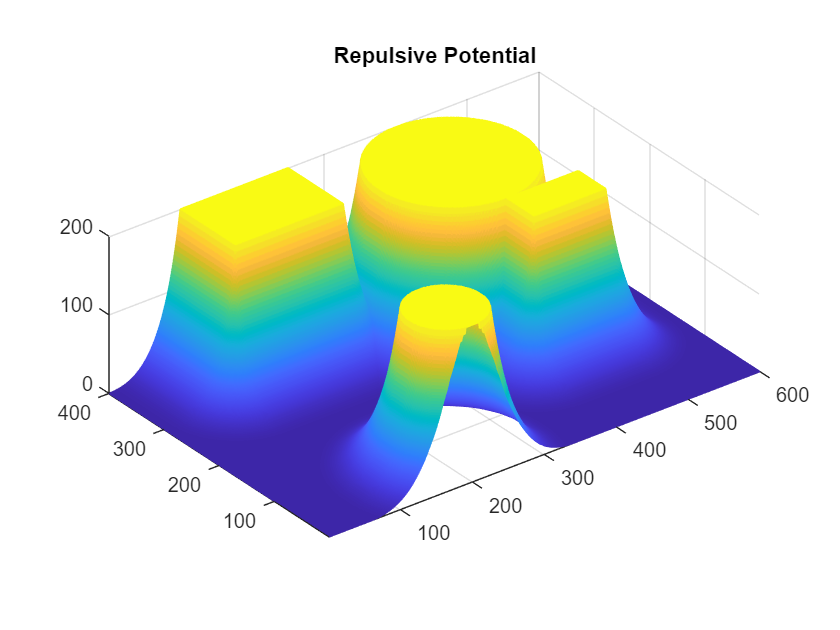

figure;
m = mesh (repulsive);
m.FaceLighting = 'phong';
axis equal;

title ('Repulsive Potential');

## Compute Attractive Force

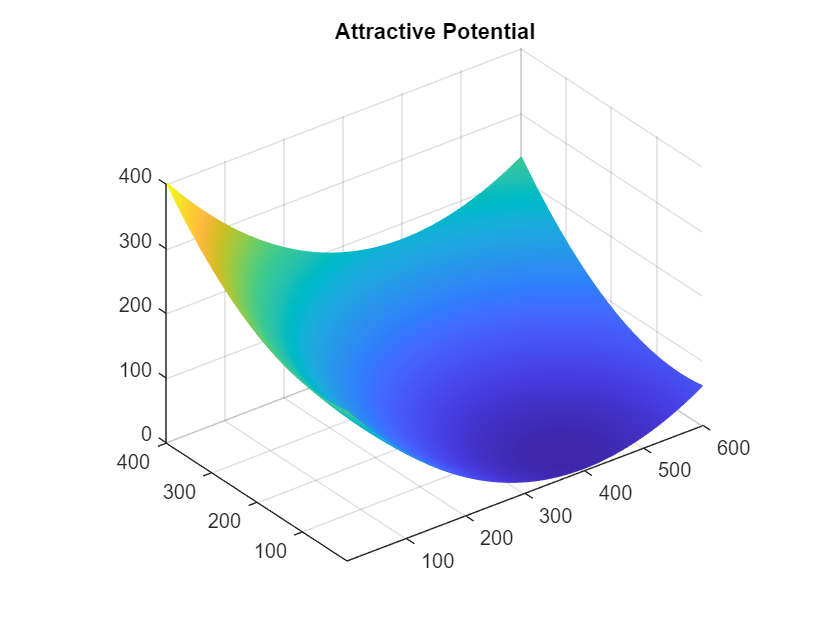

goal = [400, 50];

xi = 1/700;

attractive = xi * ( (x - goal(1)).^2 + (y - goal(2)).^2 );

figure;
m = mesh (attractive);
m.FaceLighting = 'phong';
axis equal;

title ('Attractive Potential');

## Display 2D Configuration Space

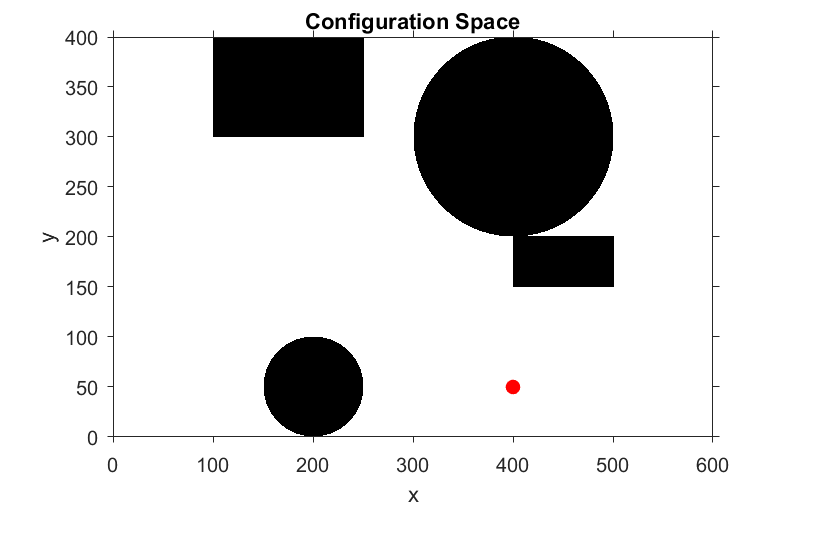

figure;
imshow(~obstacle);

hold on;
plot (goal(1), goal(2), 'r.', 'MarkerSize', 25);
hold off;

axis ([0 ncols 0 nrows]);
axis xy;
axis on;

xlabel ('x');
ylabel ('y');

title ('Configuration Space');

## Combine Terms

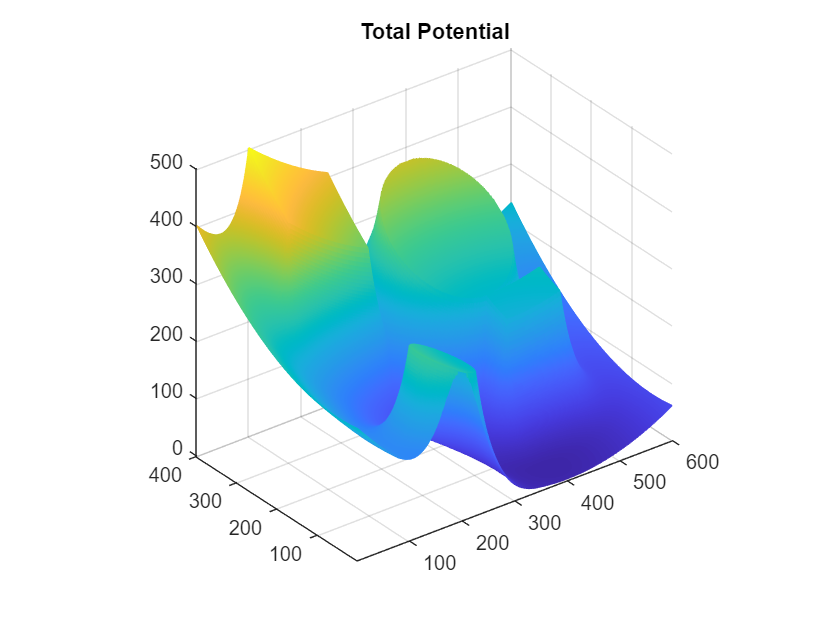

f = attractive + repulsive;

figure;
m = mesh (f);
m.FaceLighting = 'phong';
axis equal;

title ('Total Potential');

## Plan Route

start = [50, 350];
route = GradientBasedPlanner (f, start, goal, 1000);

## Plot the Energy Surface

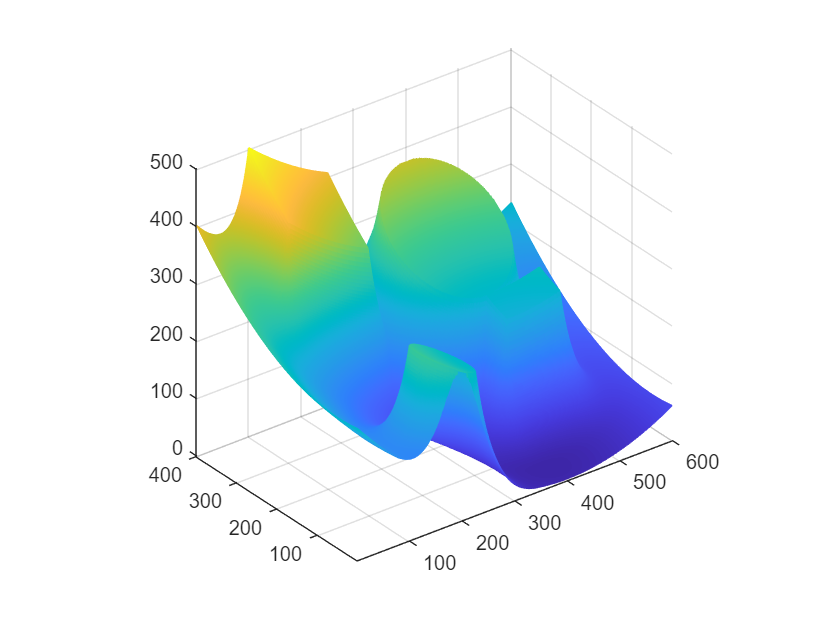

figure;
m = mesh (f);
axis equal;

## Plot Ball Sliding Down Hill

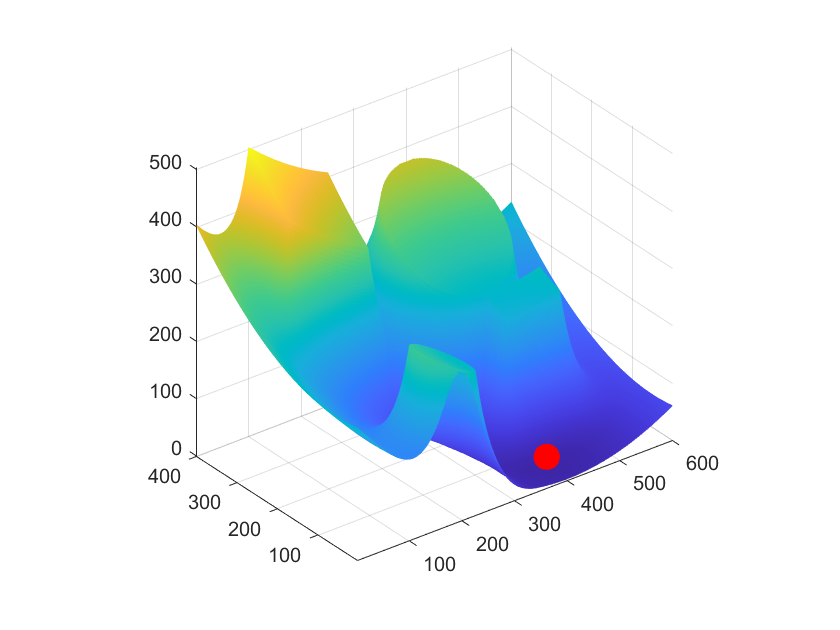

[sx, sy, sz] = sphere(20);

scale = 20;
sx = scale*sx;
sy = scale*sy;
sz = scale*(sz+1);

hold on;
p = mesh(sx, sy, sz);
p.FaceColor = 'red';
p.EdgeColor = 'none';
p.FaceLighting = 'phong';
hold off;

for i = 1:size(route,1)
    P = round(route(i,:));
    z = f(P(2), P(1));
    
    p.XData = sx + P(1);
    p.YData = sy + P(2);
    p.ZData = sz + f(P(2), P(1));
    
    drawnow;
    
    drawnow;
    
end

## Quiver Plot

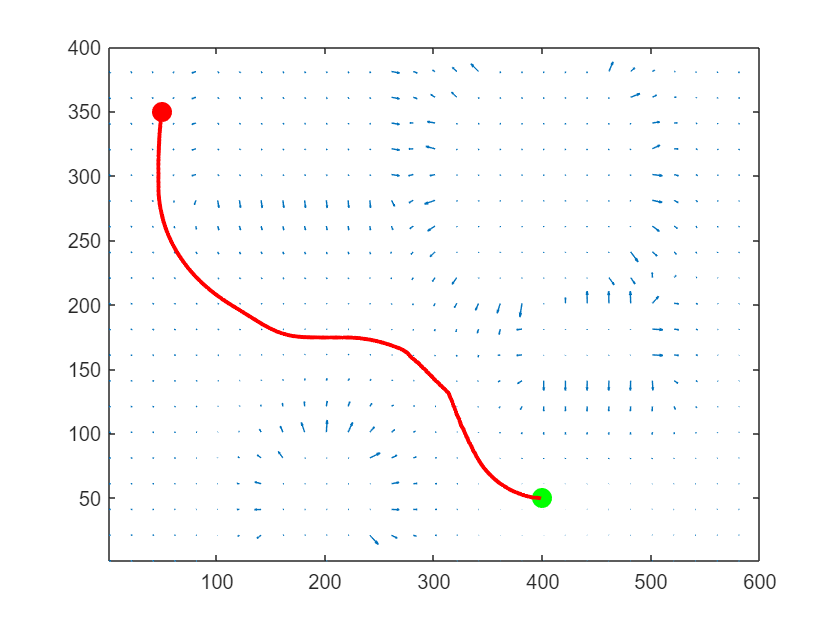

[gx, gy] = gradient (-f);
skip = 20;

figure;

xidx = 1:skip:ncols;
yidx = 1:skip:nrows;

quiver (x(yidx,xidx), y(yidx,xidx), gx(yidx,xidx), gy(yidx,xidx), 0.4);

axis ([1 ncols 1 nrows]);
hold on;

ps = plot(start(1), start(2), 'r.', 'MarkerSize', 30);
pg = plot(goal(1), goal(2), 'g.', 'MarkerSize', 30);
p3 = plot (route(:,1), route(:,2), 'r', 'LineWidth', 2);